# Larger networks

3 communities = 1 hub + 2 local

20 nodes per community

Stimulate 5 nodes of hub community

Inhibitory self connections

stim_options = get_default_stim_options();
stim_options.num_comms = 3;
stim_options.num_nodes_per_comm = 20;
stim_options.in_dsity = .55;
stim_options.out_dsity = .05;
stim_options.hub_dsity = .30;
stim_options = make_connectivity_matrix(stim_options);

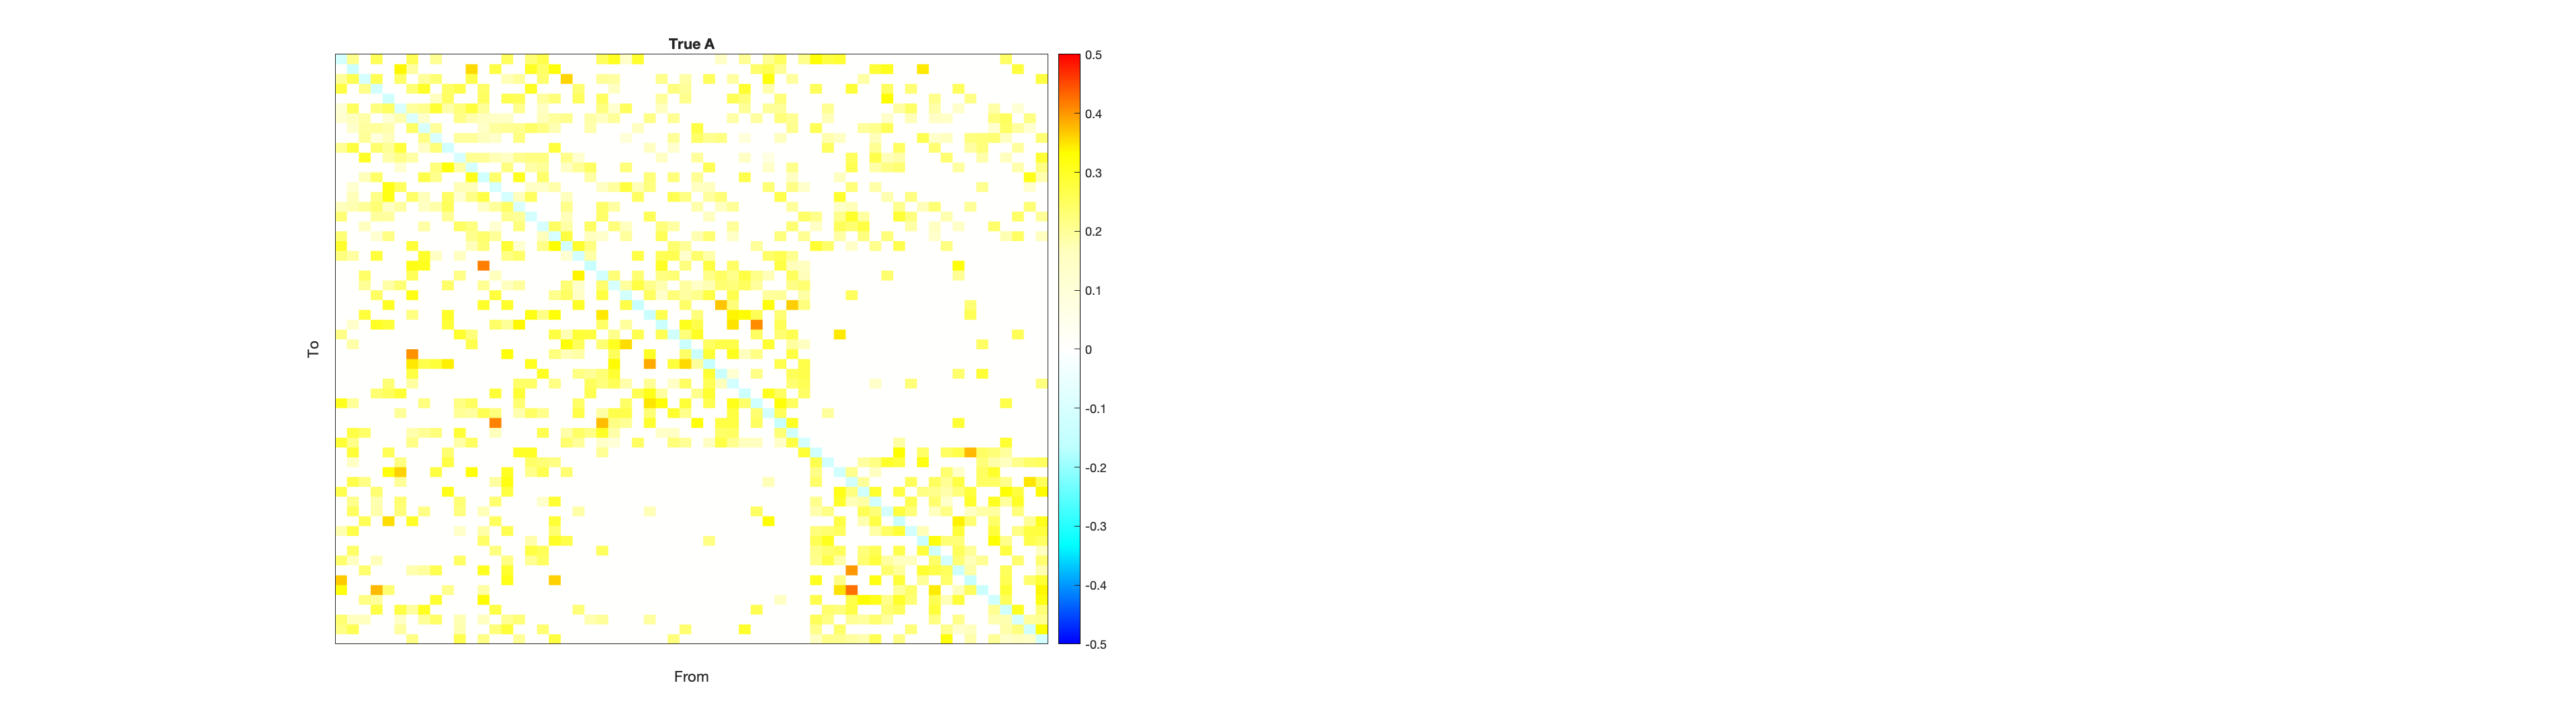

cmap = mycmap();   

f = figure();

subplot(1, 2, 1)
h = heatmap(stim_options.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A"); 
xlabel("From");
ylabel("To");

grid(h, 'off');
h.XDisplayLabels = repmat(" ", size(stim_options.Tp.A, 1), 1);
h.YDisplayLabels = repmat(" ", size(stim_options.Tp.A, 1), 1);

set(f,'Units','normalized','Position',[0 0 1 .5]); 

on_len = 16;
off_len = 8;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = 1:5;
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

[DCM, options] = make_task_fmri(stim_options);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in tapas_dcm_euler_gen (line 54)
C = DCM.U.u*(Ep.C'/16);

Error in tapas_rdcm_generate (